[sig_drums, fs_drums] = audioread('./sounds/drums.wav');
[sig_soft_piano, fs_soft_piano] = audioread('./sounds/piano-soft.wav');



Logical Computation of Decay length and Delay lengths for the FDN.

rt60 = 6;
roomsize_m = 60;
roomsize_ms = 1000*roomsize_m/343.2;

%%How long the signal take to go around the feedback loopsurfaces. This makes the effective distance longer than just the roomSizeMs itself.
% > Sound doesn't travel straight across the room but bounce off walls and other surfaces.
% > Effective distance should be longer than the roomsize_ms.
extendedloop_ms = roomsize_ms*1.5; 

%%How many times will go around during our RT60 period
loops_per_rt60 = rt60/(extendedloop_ms*0.001);

%%How many dB to reduce per loop
db_per_cycle = -60/loops_per_rt60;

fb_gains = 10^(db_per_cycle * 0.05);

D = [abs(randn(1, 8) * extendedloop_ms)]; %delays
G = repmat(fb_gains,1,8); %gains

Tests on found parameters

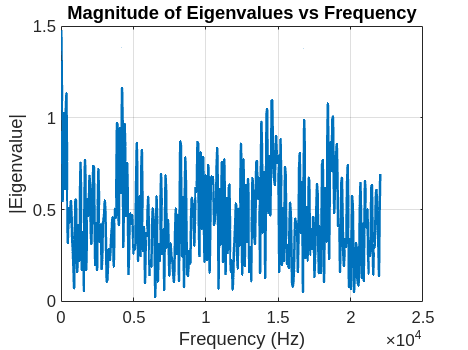

% Parameters
n = 8; % Number of delays

D = D; % Delays in milliseconds
gains = G; % Diagonal gains (values between 0 and 1)

fs = 44100; % Sampling frequency in Hz
f = linspace(0, fs / 2, 500); % Frequency range (0 to Nyquist)
omega = 2 * pi * f / fs; % Angular frequencies

% Compute eigenvalues
lambda = zeros(size(omega)); % Initialize eigenvalue storage
scaling_factor = -2 / n; % Scaling factor for M

for k = 1:length(omega)
    % Compute phase shifts z^(-D)
    z_D = exp(-1j * omega(k) * D);
    
    % Compute eigenvalue as a sum
    lambda(k) = scaling_factor * sum(gains .* z_D);
end

% Plot the magnitude of eigenvalues
figure;
plot(f, abs(lambda), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('|Eigenvalue|');
title('Magnitude of Eigenvalues vs Frequency');
grid on;

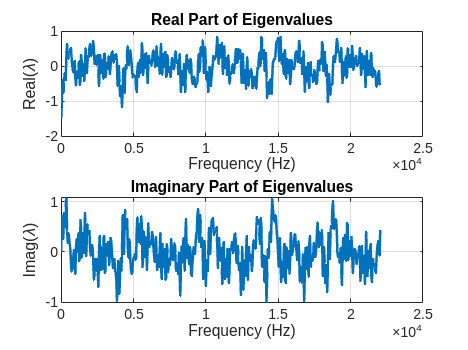


% Optional: Plot real and imaginary parts separately
figure;
subplot(2, 1, 1);
plot(f, real(lambda), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Real(\lambda)');
title('Real Part of Eigenvalues');
grid on;

subplot(2, 1, 2);
plot(f, imag(lambda), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Imag(\lambda)');
title('Imaginary Part of Eigenvalues');
grid on;

Report Examples

% Parameters
nbr_ch = 8; % Number of delays
reverb_pct = 0.6;
nbr_diff = 5;
diff_delays=[48,96,192,384,768];
D = [101, 113, 139, 151, 163, 173, 181, 199]; % Delays in milliseconds
gains = [0.35, 0.35, 0.45, 0.45,0.75, 0.25, 0.35, 0.55]; % Diagonal gains (values between 0 and 1)
early_reflections_pct = 0.4;
static_filter_freq=false;

reverb = myFirstReverb(sig_soft_piano, fs_soft_piano, nbr_ch, reverb_pct , nbr_diff,diff_delays,D',gains',early_reflections_pct, static_filter_freq);

Extending channels: 2 to 8

soundsc(reverb, fs_click)




% Parameters
nbr_ch = 8; % Number of delays
reverb_pct = 0.4;
nbr_diff = 5;
diff_delays=[48,96,192,384,768];
D = [101, 113, 139, 151, 163, 173, 181, 199]; % Delays in milliseconds
gains = [0.35, 0.35, 0.45, 0.45,0.75, 0.25, 0.35, 0.55]; % Diagonal gains (values between 0 and 1)
early_reflections_pct = 0.2;
static_filter_freq=false;

reverb = myFirstReverb(sig_drums, fs_drums, nbr_ch, reverb_pct , nbr_diff,diff_delays,D',gains',early_reflections_pct, static_filter_freq);

Extending channels: 2 to 8

soundsc(reverb, fs_click)


Check for stability regarding the chosen parameters:

% Parameters

Extending channels: 2 to 8

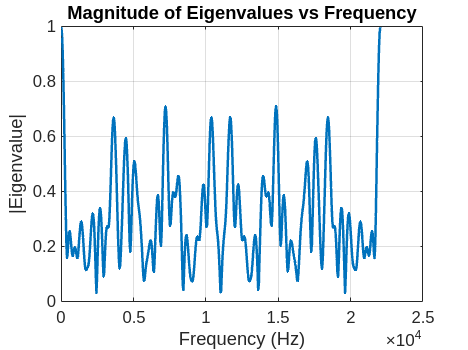

n = 8; % Number of delays

D = [101, 113, 139, 151, 163, 173, 181, 199]; % Delays in milliseconds
gains = [0.35, 0.35, 0.45, 0.45,0.75, 0.25, 0.35, 0.55]; % Diagonal gains (values between 0 and 1)

fs = 44100; % Sampling frequency in Hz
f = linspace(0, fs / 2, 500); % Frequency range (0 to Nyquist)
omega = 2 * pi * f / fs; % Angular frequencies

% Compute eigenvalues
lambda = zeros(size(omega)); % Initialize eigenvalue storage
scaling_factor = -2 / n; % Scaling factor for M

for k = 1:length(omega)
    % Compute phase shifts z^(-D)
    z_D = exp(-1j * omega(k) * D);
    
    % Compute eigenvalue as a sum
    lambda(k) = scaling_factor * sum(gains .* z_D);
end

% Plot the magnitude of eigenvalues
figure;
plot(f, abs(lambda), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('|Eigenvalue|');
title('Magnitude of Eigenvalues vs Frequency');
grid on;

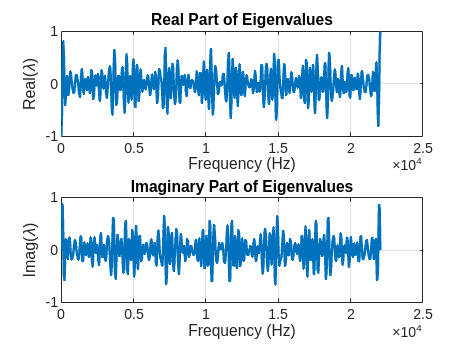


% Optional: Plot real and imaginary parts separately
figure;
subplot(2, 1, 1);
plot(f, real(lambda), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Real(\lambda)');
title('Real Part of Eigenvalues');
grid on;

subplot(2, 1, 2);
plot(f, imag(lambda), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Imag(\lambda)');
title('Imaginary Part of Eigenvalues');
grid on;

Comparison Plots:

signal = sig_soft_piano;

% Parameters
nbr_ch = 8; % Number of delays
reverb_pct = 0.6;
nbr_diff = 5;
diff_delays=[48,96,192,384,768];

diff_delays =     48    96   192   384   768


D = [101, 113, 139, 151, 163, 173, 181, 199]; % Delays in milliseconds
gains = [0.35, 0.35, 0.45, 0.45,0.75, 0.25, 0.35, 0.55]; % Diagonal gains (values between 0 and 1)
early_reflections_pct = 0.4;
static_filter_freq=false;

static_filter_freq = logical
   0



reverb = myFirstReverb(signal, fs_soft_piano, nbr_ch, reverb_pct , nbr_diff,diff_delays,D',gains',early_reflections_pct, static_filter_freq);

Extending channels: 2 to 8

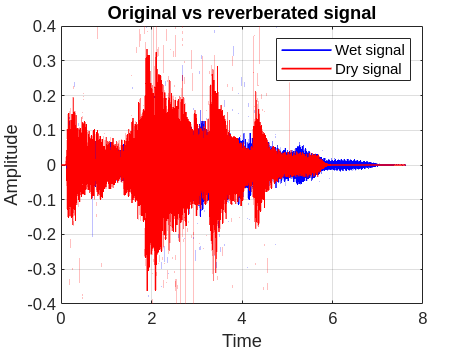

%soundsc(reverb, fs_soft_piano)

x = [1:size(reverb,1)]/fs_soft_piano;
original = vertcat(signal, zeros(size(reverb,1)-size(signal,1),2));
% Create the figure
figure;

% Plot the third wave (background) with transparency
plot(x,reverb, 'b-', 'LineWidth', 1); % Background plot
hold on;

plot(x,original, 'r-', 'LineWidth', 1); % Foreground plot

% Add labels and legend
xlabel('Time');

ylabel('Amplitude');
title('Original vs reverberated signal');
legend({'Wet signal','', 'Dry signal'});

% Adjust axes
grid on;
hold off;

signal = sig_drums;

% Parameters
nbr_ch = 8; % Number of delays
reverb_pct = 0.4;
nbr_diff = 5;
diff_delays=[48,96,192,384,768];
D = [101, 113, 139, 151, 163, 173, 181, 199]; % Delays in milliseconds
gains = [0.35, 0.35, 0.45, 0.45,0.75, 0.25, 0.35, 0.55]; % Diagonal gains (values between 0 and 1)
early_reflections_pct = 0.2;
static_filter_freq=false;

reverb = myFirstReverb(signal, fs_drums, 8, 0.4, 5,[48,96,192,384,768],[101, 113, 139, 151, 163, 173, 181, 199]',[0.35, 0.35, 0.45, 0.45,0.75, 0.25, 0.35, 0.55]',0.2, false);

Extending channels: 2 to 8

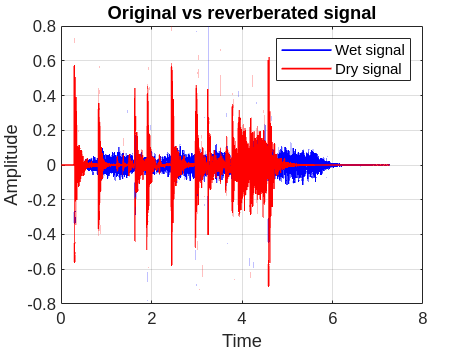

%soundsc(reverb, fs_drums)

x = [1:size(reverb,1)]/fs_drums;
original = vertcat(signal, zeros(size(reverb,1)-size(signal,1),2));
% Create the figure
figure;

% Plot the third wave (background) with transparency
plot(x,reverb, 'b-', 'LineWidth', 1); % Background plot
hold on;

plot(x,original, 'r-', 'LineWidth', 1); % Foreground plot

% Add labels and legend
xlabel('Time');

ylabel('Amplitude');
title('Original vs reverberated signal');
legend({'Wet signal','', 'Dry signal'});

% Adjust axes
grid on;
hold off;